# Table 1

dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")
head(data,5)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index    Current    Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    _______    _______    _______________    __________________    _____________    ________________    ___________    ___________________    ___________

## Chart

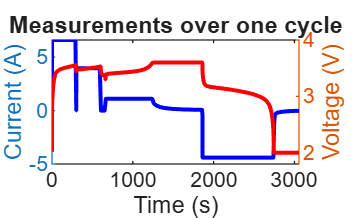

cycleData = data(data.Cycle_Index == 1, :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
figure;
yyaxis left;
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current (A)');
yyaxis right;
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
xlabel("Time (s)");
title('Measurements over one cycle');

## Table 2

bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable= "Voltage";
bParser.TimeVariable = "DateTime";
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  

## Chart 2

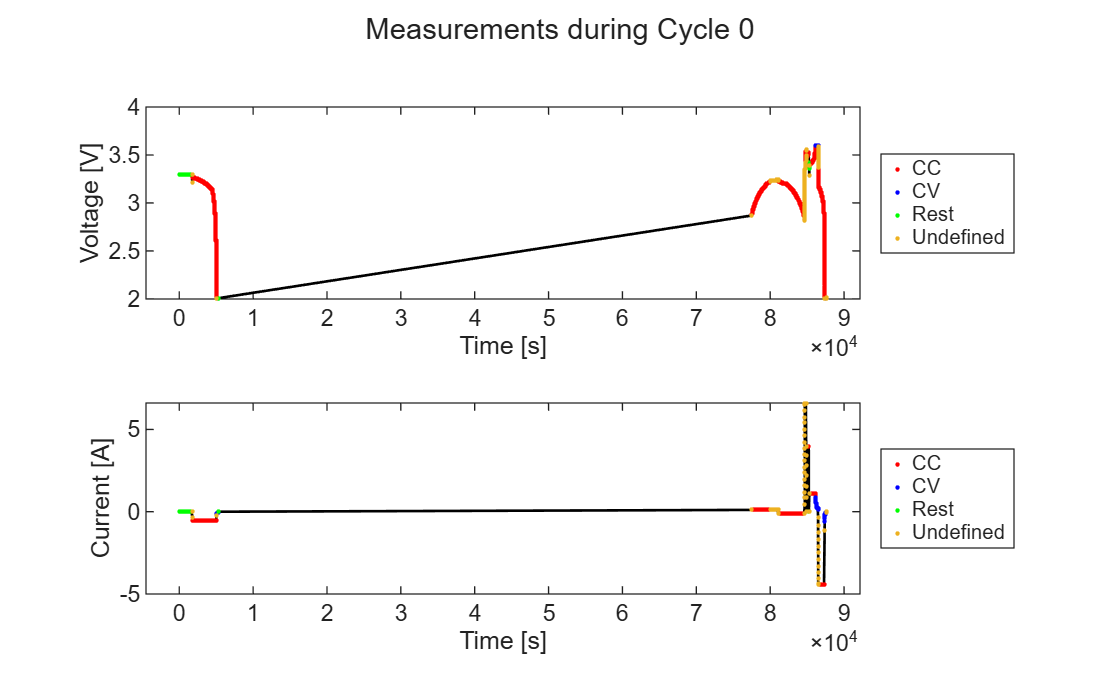

cycleList = unique(segmentedRawDataTable(segmentedRawDataTable.IsValid, :).Cycle_Index);
maxCycle = max(cycleList);
cycleIndex = 0;
hPlotRawMeasurementsWithSegments(segmentedRawDataTable, bParser, cycleIndex)